# Signals and Systems - Dr.Akhavan

## CA3 - Matin Bazrafshan 

# Part 1:

#### 1.1 create mapset

First step is creating a mapset, a 5-bit string will be mapped to every charachter, so it can be used to encode or decode later.

mapset = create_mapset();
mapset

mapset = 2×32 cell array
    {'a'    }    {'b'    }    {'c'    }    {'d'    }    {'e'    }    {'f'    }    {'g'    }    {'h'    }    {'i'    }    {'j'    }    {'k'    }    {'l'    }    {'m'    }    {'n'    }    {'o'    }    {'p'    }    {'q'    }    {'r'    }    {'s'    }    {'t'    }    {'u'    }    {'v'    }    {'w'    }    {'x'    }    {'y'    }    {'z'    }    {' '    }    {'.'    }    {','    }    {'!'    }    {'"'    }    {';'    }
    {'00000'}    {'00001'}    {'00010'}    {'00011'}    {'00100'}    {'00101'}    {'00110'}    {'00111'}    {'01000'}    {'01001'}    {'01010'}    {'01011'}    {'01100'}    {'01101'}    {'01110'}    {'01111'}    {'10000'}    {'10001'}    {'10010'}    {'10011'}    {'10100'}    {'10101'}    {'10110'}    {'10111'}    {'11000'}    {'11001'}    {'11010'}    {'11011'}    {'11100'}    {'11101'}    {'11110'}    {'11111'}


#### 1.2 Load image

pic = imread('sample.png');
pic = rgb2gray(pic);

#### 1.3 Encode message

To encode a message into pixels of an image, first we make a bit string equal to our message according to mapset, then we put every bit in LSB (least significant bit) of a pixel in a specific order(here, row by row). Take note that a message should end with a semicolon, so decoder will be able to determines where it must end decoding.

message = 'signal;';
coded_pic = coding(pic, message, mapset);

#### 1.4 Compare coded and original images

After encoding, we can see there is no sensible difference between two pictures, the reaseon is that just value of some pixels has been changed, at most 1, so it can not be distinguished.

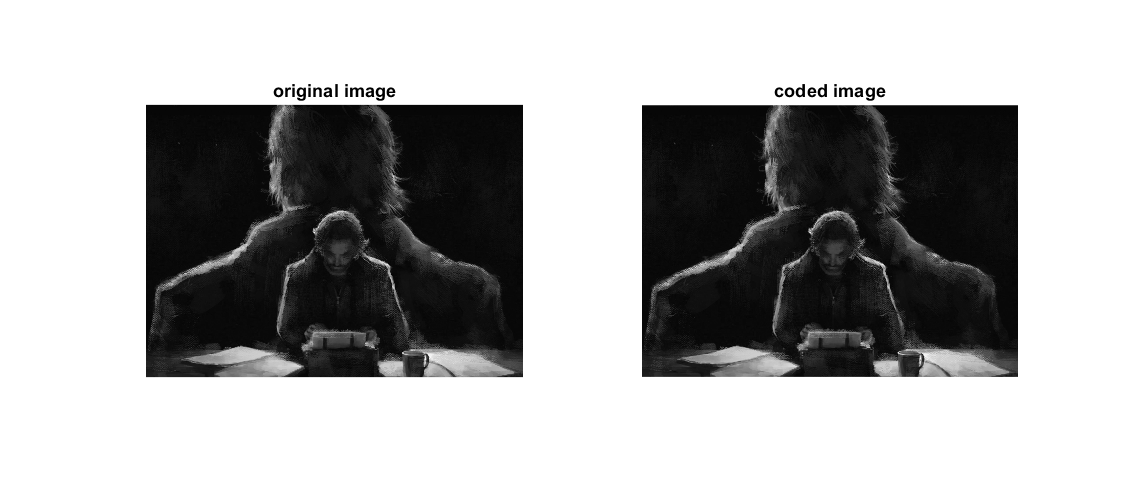

figure('Position', [0 0 900 400]);
subplot(1,2,1);
imshow(pic);
title('original image');
subplot(1,2,2);
imshow(coded_pic);
title('coded image');

#### 1.5 Decode image

According to the `mapset, `encoding order and the fact that a message ends with semicolon `;` we can decode a pixel.

coded_message = decoding(coded_pic, mapset);
disp(coded_message);

signal;


#### 1.6 Noise adding:

We should use error detection and error correction algorithm, there are two cases:

- The noise is limited and we know number of bit errors are limited, in this case we can use some error correction codes such as CRC and Hamming code.

- We are in noisy case and all bits can be missent, so there is no way to detect all errors, if there is no limitation or heuristic about it.

One of the most useful error correction code is Hamming code.

- Hamming codes add extra bits to the original data to detect and correct errors. The positions of the extra bits are determined by powers of 2. The values of the extra bits are calculated based on the data bits, ensuring that the parity of certain groups of bits is correct. The receiver uses these extra bits to check for and correct error

#### 1.7 Coding detection

Two case can happen:

- We know coding method: in this case we can apply decoding on image, if we got a sensible result we can understand it

- We do not know coding method: in this case we should use some statistical analysis.

** statistical analysis:**

- letter distribution and word probabilities in NLP: by knowing some hyperparameters about language we are decoding(this datas are available due to NLP, we can detect some pixel distribution mapped to letter/word distribution we have.

- Chi-Square Test: The chi-square test can be applied to compare the observed pixel distribution in an image with the expected distribution. Significant deviations may indicate the presence of hidden data.

# Part 2:

DTMF (Dual-Tone Multi-Frequency) is a signaling method used in telecommunication systems to transmit digits, symbols, or control signals over voice channels.

#### 2.1 Defining constants

First we need to define some constants such as high and low frequencies, on and off time, sampling rate and etc.

high_freq = [1209, 1336, 1447];
low_freq = [697, 770, 852, 941];

Ton = 0.1;
Toff = 0.1;
fs = 8000;

number = '8';
audio_reset = zeros(1, fs * Toff);


#### 2.2 Synthesize touch tone

Now we just need to generate a wave with given frequencies and add a reset(zero signal with length of $T_{off}$), and repeat this for all numbers.

y = [];
for i = 1:length(number)
    tone = generate_dtmf(number(i), low_freq, high_freq, fs, Ton);
    y = [y, tone];
    y = [y, audio_reset]; 
end
sound(y, fs);

#### 2.3 Analyze DTMF (Dual-Tone Multi Frequency)

We need to extraxt generated signals from audio, which means removing zero signals, the calculate correlation of signals with our mapset which is signal of a number based on frequecy table.

[input_signal, fs] = audioread('sample.wav');
input_signal = transpose(input_signal);
on_signal_len = fs * Ton;
coded_number = '';
keypad = [char('0' : '9'), '*', '#'];

%input_signal = y;
for i = 0:2:(size(input_signal,2) / on_signal_len) - 2
    sliced_signal = input_signal(on_signal_len * i + 1 : on_signal_len * (i + 1));
    max_corr = -inf;
    max_key = '-';
    for j = 1:length(keypad)
        template_signal = generate_dtmf(keypad(j), low_freq, high_freq, fs, Ton);
        corr_j = xcorr(sliced_signal, template_signal);
        if(max(abs(corr_j)) > max_corr)
            max_corr = corr_j;
            max_key = keypad(j);
        end
        
    end
    coded_number = [coded_number, max_key];
end

disp(coded_number);

810198


# Part 3:

#### 3.1 Load and preprocess

First we load images and make the 2D arrays by removing rgb and make the grayscale.

template = imread('IC.png');
template = rgb2gray(template);

pic = imread('PCB.jpg');
grayed_pic = rgb2gray(pic);

#### 3.2 Template matching

To do this we need to do cross-correlation but we must consider we need to calculate normalized correlation, beacuse we need to treat numbers equally so for example a white pixel(with value of 255) do not make a bigger number than a black pixel(with value of 0) due to dot product.

The pixels must be noramlized: 

so we calculate normalized correlation of 2D arrays(images).


$$corr2_{norm}(A, B) = \frac{{\sum_{i,j}(A[i,j] )(B[i,j])}}{{\sqrt{{\sum_{i,j}(A[i,j]^2 \sum_{i,j}(B[i,j])^2}}}}$$


To find most correlation, we need to slice rectangles from our image with the same size of our template, calculate the correlation, and find the most one, this is called cross-correlation, we stop this procedure when the most correlation was lower than a threshold(0.6 in this case).


$$\text{{CrossCorrelation}}(A, B) = max(\sum_{i=1}^{H_A - H_B + 1} \sum_{j=1}^{W_A - W_B + 1} corr2(A[i:i + H_B - 1][j:j + W_B- 1], B))$$


- A is our image

- B is our template

According to the problem, the template can also rotate 180 degrees, we calculate correlations for two templates.

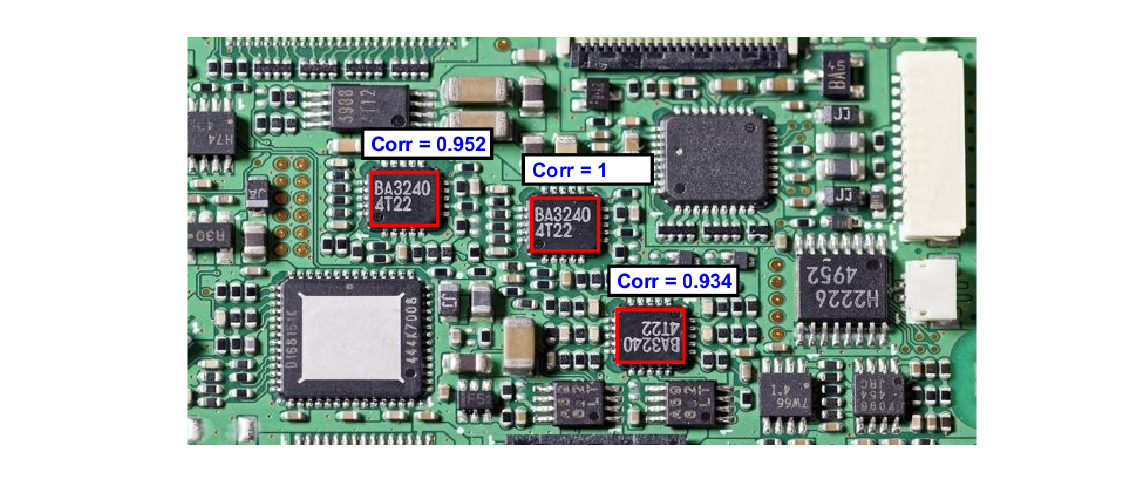

figure('Position', [0 0 900 400]);
imshow(pic);
hold on;

for rotates = 1:2
    while(1)
        [max_corr, row_begin, col_begin] = cross_correlation(template, grayed_pic);
        height = size(template, 1);
        width = size(template, 2);
        row_end = row_begin + height - 1;
        col_end = col_begin + width - 1;
        grayed_pic(row_begin:row_end, col_begin:col_end) = 0;
        if(max_corr < 0.9)
            break;
        end
        rectangle('Position', [col_begin, row_begin, width, height], 'EdgeColor', 'red' ,'LineWidth', 2);
        rectangle('Position', [col_begin - 7, row_begin - 37, 110, 25], 'FaceColor', 'white' ,'LineWidth', 2);
        text(col_begin, row_begin - 25, "Corr = " + num2str(max_corr,3), 'Color' , 'blue', 'FontSize', 12 ,'FontWeight', 'bold');
    end
    template = imrotate(template, 180); % 0 - 90 - 180 - 270
end

# Functions

All implemented functions can be found here:

function [mapset] = create_mapset()
    mapset = cell(2, 32);
    list = char('a':'z');
    list = [list ,' ', '.', ',','!', '"', ';'];

    for i = 1:32
        character = list(i);
        bit_string =  dec2bin(i - 1, 5);
        mapset{1, i} = character;
        mapset{2, i} = bit_string;
    end
end

function [coded_picture] = coding(pic, message, mapset)
    coded_picture = pic;
    n_rows = size(pic,1);
    n_cols = size(pic,2);
    
    if(5 * length(message) > n_rows * n_cols)
        error('message length is bigger than image size');
    end
     
    
    for i = 1:length(message)
        bit_string = mapset{2, strcmp(mapset(1,:), message(i))};
        for j = 1:5
            k = (i - 1) * 5 + j;
            row = ceil(k / n_cols);
            col = mod(k - 1, n_cols) + 1;
            if(mod(pic(row,col), 2) == 0 && bit_string(j) == '1')
                coded_picture(row,col) = pic(row,col) + 1;
            elseif(mod(pic(row,col), 2) == 1 && bit_string(j) == '0')
                coded_picture(row,col) = pic(row,col) - 1;
            end
        end
    end
end

function [code] = decoding(coded_pic, mapset)
    n_cols = size(coded_pic,2);

    i = 1;
    code = '';
    while(1)
        bit_string = '';
        for j = (5 * (i - 1) + 1):(5 * i)
            row = ceil(j / n_cols);
            col = mod(j - 1, n_cols) + 1;
            if(mod(coded_pic(row,col), 2) == 0)
               bit_string = [bit_string, '0'];
            else
                bit_string = [bit_string, '1'];
            end
        end
        char = mapset{1, strcmp(mapset(2,:), bit_string)};
        code = [code, char];
        if(strcmp(char, ';'))
            break;
        end
        i = i + 1;
    end     
end


function [res] = simple_corr(arr1, arr2)
    res = dot(arr1, arr2);
end

function [y] = generate_dtmf(key, low_freq, high_freq, fs, Ton)
    [LF_index, HF_index] = freq_index(key);
    Ts = 1 / fs;
    t = 0:Ts:(Ton - Ts);
    y_low = sin(t * 2 * pi * low_freq(LF_index));
    y_high = sin(t * 2 * pi * high_freq(HF_index));
    
    y = (y_low + y_high) / 2;
end

function [low, high] = freq_index(key)
    if(strcmp(key, '*'))
        low = 4;
        high = 1;
        return;
    end
    if(strcmp(key, '#'))
        low = 4;
        high = 3;
        return;
    end
    key = str2num(key);
    if(key == 0)
        low = 4;
        high = 2;
    else
        low = ceil(key / 3);
        high = mod(key - 1, 3) + 1;
    end
end

function [s] = sum2(a)
    s = sum(a(:));
end

function [r] = normalized_corr(a, b)
    % alternative approach
    % a = (a - mean2(a)) / std2(a);
    % b = (b - mean2(b)) / std2(b);
    a = double(a);
    b = double(b);
    r = sum2(a .* b) / sqrt(sum2(a .* a) * sum2(b .* b));
end

function [max_corr, max_row , max_col] = cross_correlation(template, image)
    w_image = size(image, 2);
    h_image = size(image, 1);
    w_template = size(template, 2);
    h_template = size(template, 1);
    if(w_template > w_image || h_template > h_image)
        error('template must be smaller than image');
    end
    

    max_corr = -inf;
    max_row = -1;
    max_col = -1;
    
    for i = 1:(w_image - w_template + 1)
        for j = 1:(h_image - h_template + 1)
            sliced_image = image(j : (j + h_template - 1), i : (i + w_template - 1));
            corr_slice = normalized_corr(template, sliced_image);
            if(corr_slice > max_corr)
                max_corr = corr_slice;
                max_col = i;
                max_row = j;
            end
        end
    end
end